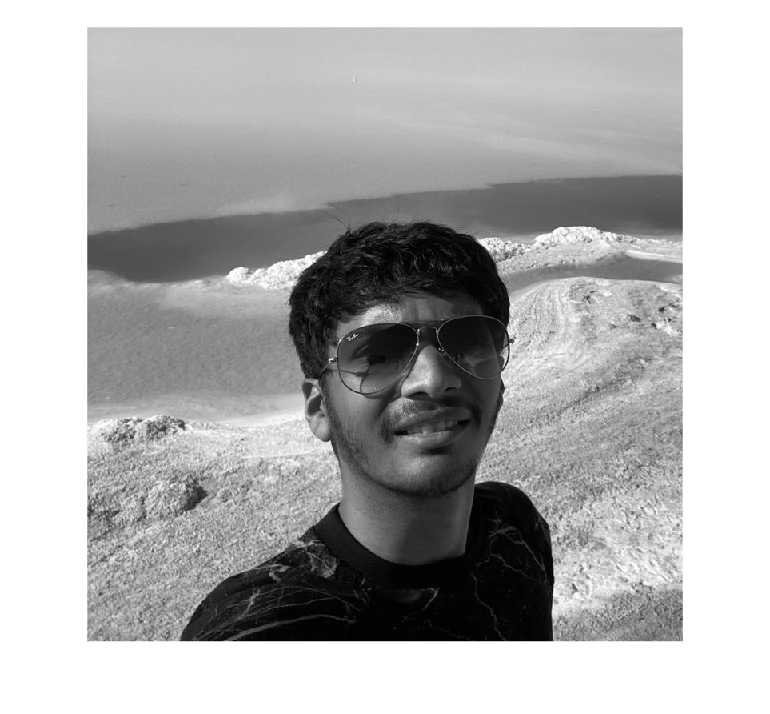

img = imread("C:\Users\snehs\Downloads\WhatsApp Image 2024-04-11 at 4.26.29 PM.jpeg");
grayimg = im2gray(img);
imshow(grayimg);

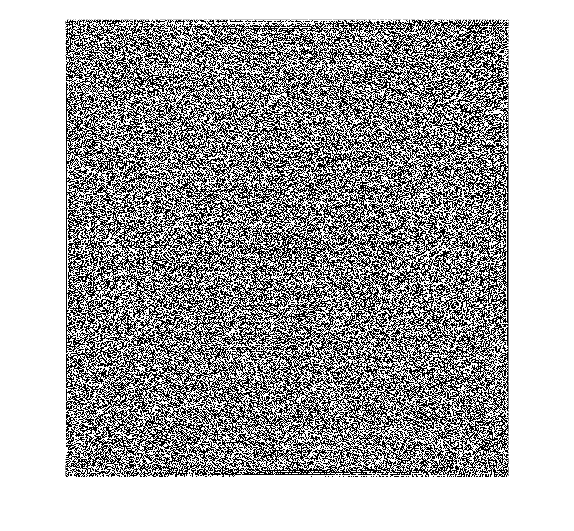

dftimg = fft2(double(grayimg)); 
imshow(dftimg);

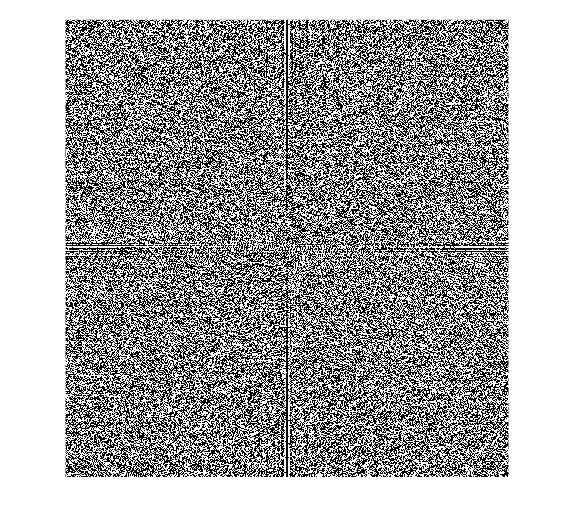

dftimg_shifted = fftshift(dftimg);
imshow(dftimg_shifted);

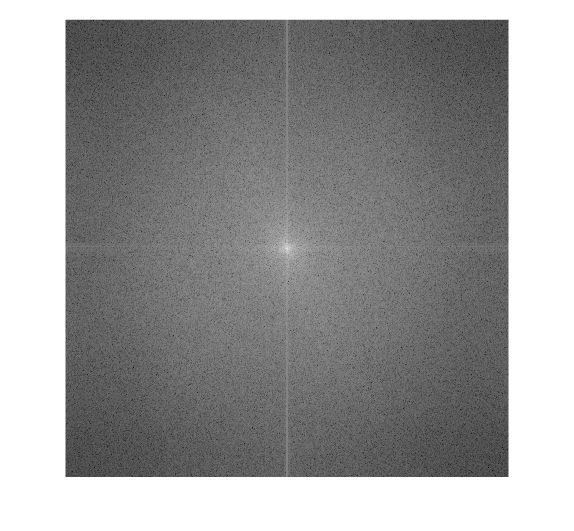

magnitude = abs(dftimg_shifted);

log_magnitude = log(1 + magnitude);
imshow(log_magnitude, []);

dftimg_shiftedagain = ifftshift(dftimg_shifted);
imshow(dftimg_shiftedagain);

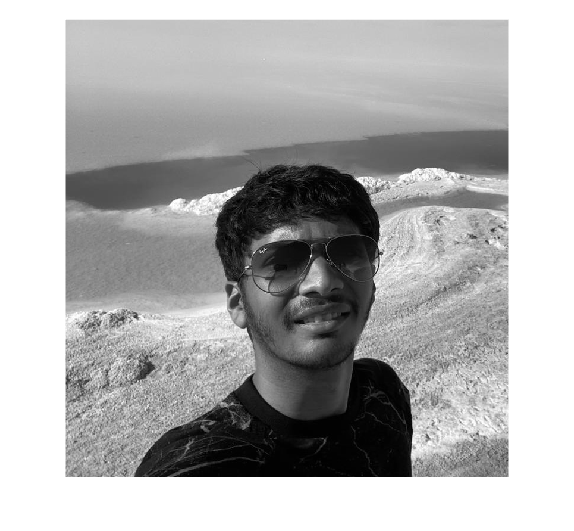

ifftimg = ifft2(dftimg_shiftedagain);
imshow(ifftimg,[]);